clc; clear; close all;

%Fixed Parameters
data = load('epidata.mat');
A = data.A;
G = graph(A);
I = 6;
rec_day = 4;
day_x = 1:30;
day = 30;

%3a)
% Recall R0 = p * k
% Let k be mean degree of network
k = mean(degree(G))

k = 4

% For p = 0.3,
p1 = 0.3;
R0_1 = p1*k

R0_1 = 1.2000

% For p = 0.6,
p2 = 0.6;
R0_2 = p2*k

R0_2 = 2.4000

v =   VideoWriter

    General Properties:

       Filename:                 'record.avi'
       Path:                     'C:\Users\ethan\OneDrive\Documents\University-of-Houston\MATH 4315\Assignment 8'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                10
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


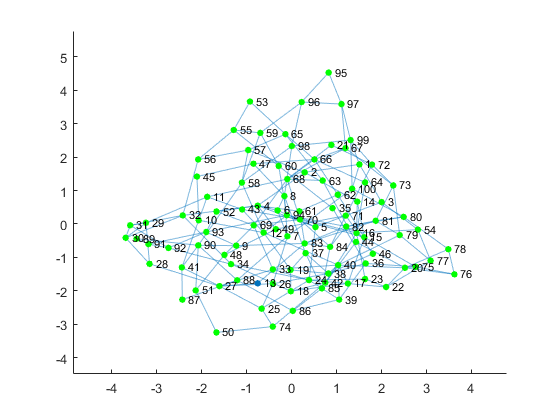

%3b)
type = 'SIR'; % 'SIR' or 'SIS'
% For p = 0.3
[nS1 nI1 nR1] = epidemic(A, I, p1, rec_day, day, type);

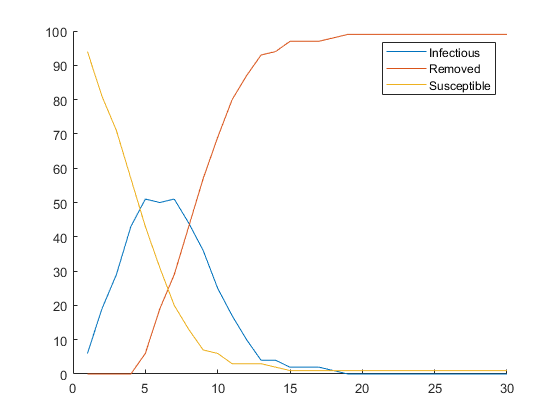

plot(day_x,nI1, day_x,nR1, day_x,nS1)
legend('Infectious', 'Removed', 'Susceptible')

v =   VideoWriter

    General Properties:

       Filename:                 'record.avi'
       Path:                     'C:\Users\ethan\OneDrive\Documents\University-of-Houston\MATH 4315\Assignment 8'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                10
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


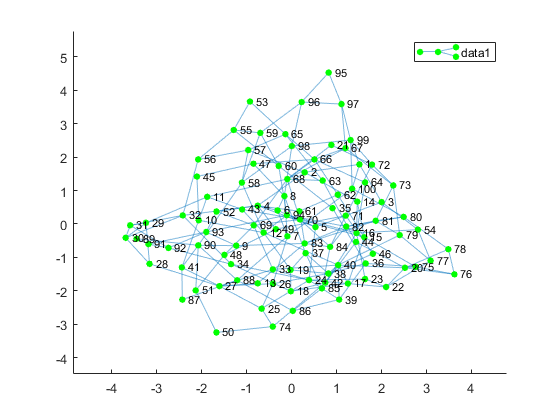

% For p = 0.6
[nS2 nI2 nR2] = epidemic(A, I, p2, rec_day, day, type);

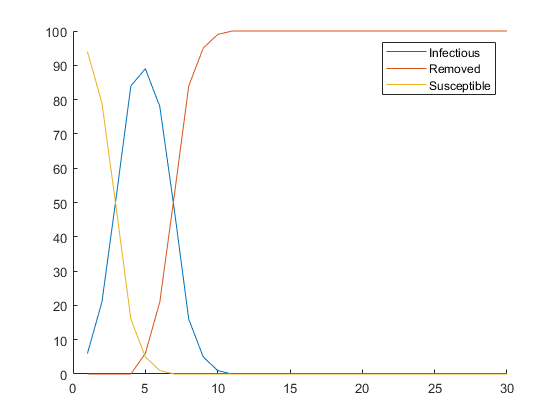

plot(day_x,nI2, day_x,nR2, day_x,nS2)
legend('Infectious', 'Removed', 'Susceptible')

% As the probability of infection is higher for p = 0.6, the time taken to
% spread is much lower, hence the higher peak of the infectious plot line
% for p = 0.6 (roughly 80) than for p = 0.3 (roughly 60). Additionally,
% since the disease spreads more quickly, it also dies out much faster as
% the number of susceptible nodes decreases much more quickly.

v =   VideoWriter

    General Properties:

       Filename:                 'record.avi'
       Path:                     'C:\Users\ethan\OneDrive\Documents\University-of-Houston\MATH 4315\Assignment 8'
       FileFormat:               'avi'
       Duration:                 0.1

    Video Properties:

       ColorChannels:            3
       Height:                   343
       Width:                    434
       FrameCount:               1
       FrameRate:                10
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


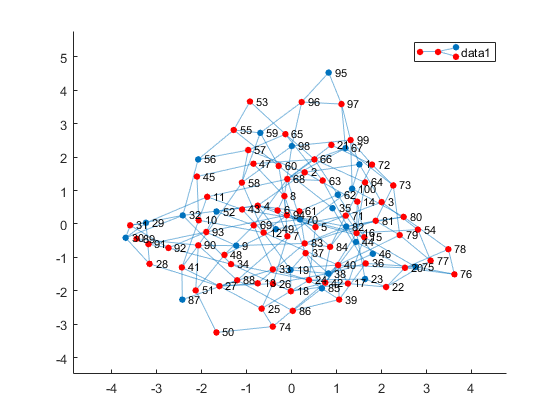

%3c)
type = 'SIS'; % 'SIR' or 'SIS'
day = 60;
day_x = 1:60;
% For p = 0.3
[nS3 nI3 nR3] = epidemic(A, I, p1, rec_day, day, type);

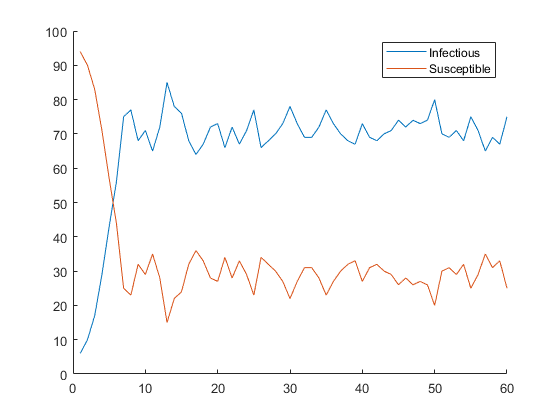

plot(day_x,nI3, day_x,nS3)
legend('Infectious', 'Susceptible')

v =   VideoWriter

    General Properties:

       Filename:                 'record.avi'
       Path:                     'C:\Users\ethan\OneDrive\Documents\University-of-Houston\MATH 4315\Assignment 8'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                10
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


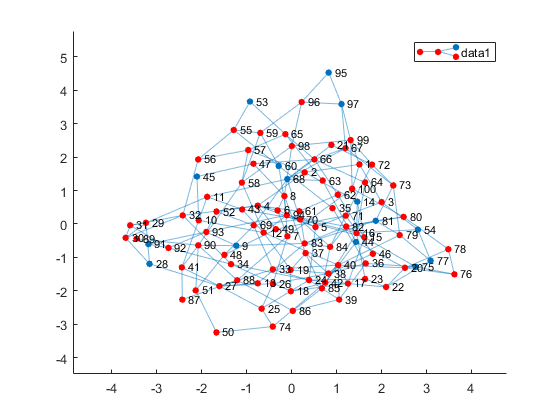

% For p = 0.6
[nS4 nI4 nR4] = epidemic(A, I, p2, rec_day, day, type);

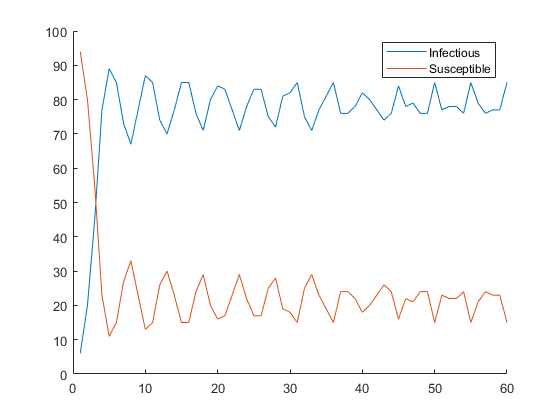

plot(day_x,nI4, day_x,nS4)
legend('Infectious', 'Susceptible')

% In the instance where there is no Removed state for nodes, i.e. nodes can
% be reinfected after they recover, the p = 0.6 scenario begins an
% oscillatory infectious and susceptible cycle. This is because the disease
% spreads very rapidly to the susceptible individuals so they all become
% infectious at similar times, therefore they all recover at roughly the
% same time. The cycle will continue in this oscillatory cycle. In contrast
% the p = 0.3 scenario will maintain a fairly constant number of infectious
% and susceptible with smaller oscillations

%3d)
%trial and error p to make nI die out
p = 0.06

p = 0.0600

v =   VideoWriter

    General Properties:

       Filename:                 'record.avi'
       Path:                     'C:\Users\ethan\OneDrive\Documents\University-of-Houston\MATH 4315\Assignment 8'
       FileFormat:               'avi'
       Duration:                 0.1

    Video Properties:

       ColorChannels:            3
       Height:                   343
       Width:                    434
       FrameCount:               1
       FrameRate:                10
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


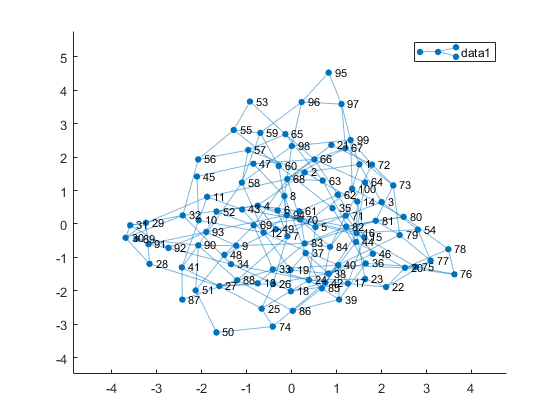

[nS5 nI5 nR5] = epidemic(A, I, p, rec_day, day, type);

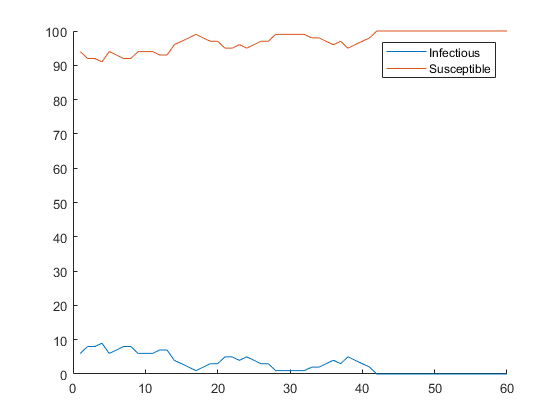

plot(day_x,nI5, day_x,nS5)
legend('Infectious', 'Susceptible')

% value slightly greater than previous p for which disease does not die out
p = 0.09

p = 0.0900

v =   VideoWriter

    General Properties:

       Filename:                 'record.avi'
       Path:                     'C:\Users\ethan\OneDrive\Documents\University-of-Houston\MATH 4315\Assignment 8'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                10
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


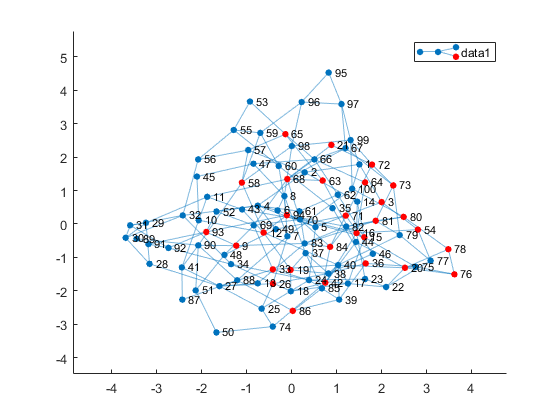

[nS6 nI6 nR6] = epidemic(A, I, p, rec_day, day, type);

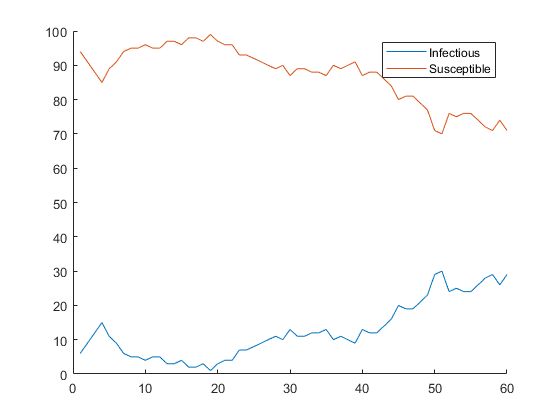

plot(day_x,nI6, day_x,nS6)
legend('Infectious', 'Susceptible')